# **GaussSL**

Lemniscate sine function

## Definition


$$\mathrm{sl}\phi =\mathrm{sin}\;\mathrm{lemn}\;\phi \equiv \mathrm{sd}\left(\phi \sqrt{2},1/\sqrt{2}\right)/\sqrt{2}$$


where *sd *is Jacobi elliptic function ([1]).

Domain: $-\infty <\phi <\infty$. For the specified domain, the  codomain is the set of real numbers.

Special values:

   
$$\mathrm{sl}\left(0\right)=0$$


Identities:


$${\mathrm{sl}}^2 \phi =\frac{1-{\mathrm{cl}}^2 \phi }{1+{\mathrm{cl}}^2 \phi }$$


## Syntax

Y = GaussSL(PHI)

y = gsl(phi)

## Description

**Y = GaussSL(PHI)** returns the value of the lemniscate sine function  for each element of the array  PHI.  PHI must be real array or scalar. **GaussSL** is the wrapper function which calls the functions **gsl** element-wise via the function **ufun1**.

**y = gsl(phi)** returns the value of  the lemniscate sine function for  phi. It is assumed that  phi is real scalars without check. y is NaN if phi is invalid or convergence failed. **gsl** is the wrapper function which calls the function **gslcl**.

 **gslcl **simultaneously  compute $\mathrm{cl}\phi$ and $\textrm{sl}\phi$ using function **sncndn ** ([2])

## Precision

## **Numerical Examples**

**Scalar input**

format long
phi = pi/2; 
[gsl(phi), GaussSL(phi)]

ans =    0.934708852843213   0.934708852843213


Accuracy. 

fprintf('%.16g\n',gsl(1)) 

0.9076832214049462


% Maple 0.9076832214049461 70

Special values

gsl(0)

ans = 0

Identities

phi = pi/4;
disp(gsl(phi)^2-(1- gcl(phi)^2)/(1 + gcl(phi)^2))

    -2.220446049250313e-16



**Vector input**

phi=[1e-6 2 3 1e20];
disp(GaussSL(phi).^2-(1- GaussCL(phi).^2)./(1 + GaussCL(phi).^2))

   1.0e-16 *

  -0.889005833412821  -0.555111512312578  -0.555111512312578                   0



**Matrix input**

phi=[-1/2 1/3 1/4; 1/2 -1/3 -1/4];
disp(GaussSL(phi).^2-(1- GaussCL(phi).^2)./(1 + GaussCL(phi).^2))

   1.0e-15 *

   0.083266726846887  -0.055511151231258  -0.131838984174237
   0.083266726846887  -0.055511151231258  -0.131838984174237



## **Plot**

**Example 1**

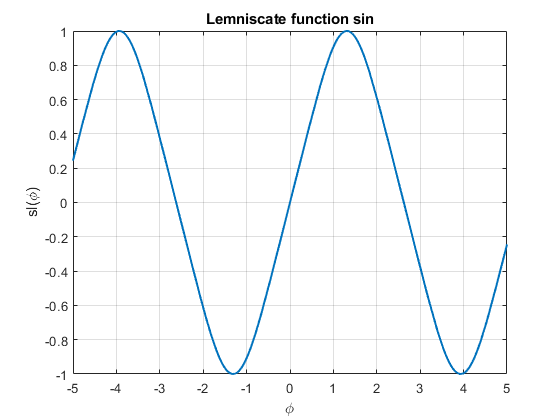

figure
fplot(@(phi) GaussSL(phi),'LineWidth',1.5)
title('Lemniscate function sin')
ylabel('sl(\phi)')
xlabel('\phi')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

[Lemniscatic elliptic function, Wikipedia](https://en.wikipedia.org/wiki/Lemniscatic_elliptic_function)

## **References**

[1] E.T. Whittaker, G.N. Watson, A course of modern analysis, 4. ed., Cambridge Univ. Pr., Cambridge, 1996.

[2]  [W.Ehrhardt, The AMath and DMath Special functions, 2016](http://www.wolfgang-ehrhardt.de/specialfunctions.pdf)

## See Also